clear;
close all;
clc;

%% Display settings

show_animation = true;
show_graphs = false;

%% Robot parameters

param = robot_parameters();

%% Initial state

q0 = [
    deg2rad(60);
    deg2rad(15)
];

dq0 = [
    0;
    0
];

x0 = [
    q0;
    dq0
];

%% Simulation settings

tspan = [0, 5.0];

options = odeset( ...
    'RelTol', 1e-7, ...
    'AbsTol', 1e-9, ...
    'MaxStep', 2e-4);

%% Run simulation
%
% Contact stiffness can make the differential equation numerically stiff.

[t, x] = ode15s( ...
    @(t, x) forward_dynamics_MCGFC( ...
        t, x, param), ...
    tspan, ...
    x0, ...
    options);

%% Extract states

q = x(:, 1:2);
dq = x(:, 3:4);

number_of_samples = length(t);

%% Allocate dynamics logs

ddq = zeros(number_of_samples, 2);

c_log = zeros(number_of_samples, 2);
G_log = zeros(number_of_samples, 2);

friction_torque_log = ...
    zeros(number_of_samples, 2);

%% Allocate Cartesian-state logs

joint_position = ...
    zeros(number_of_samples, 2);

joint_velocity = ...
    zeros(number_of_samples, 2);

ee_position = ...
    zeros(number_of_samples, 2);

ee_velocity = ...
    zeros(number_of_samples, 2);

%% Allocate contact-force logs

joint_contact_force = ...
    zeros(number_of_samples, 2);

ee_contact_force = ...
    zeros(number_of_samples, 2);

total_contact_force = ...
    zeros(number_of_samples, 2);

%% Allocate contact-torque logs

joint_contact_torque = ...
    zeros(number_of_samples, 2);

ee_contact_torque = ...
    zeros(number_of_samples, 2);

total_contact_torque = ...
    zeros(number_of_samples, 2);

%% Allocate penetration logs

joint_penetration = ...
    zeros(number_of_samples, 1);

ee_penetration = ...
    zeros(number_of_samples, 1);

%% Allocate contact-state logs

joint_contact_state = ...
    false(number_of_samples, 1);

ee_contact_state = ...
    false(number_of_samples, 1);

%% Allocate energy logs

kinetic_energy = ...
    zeros(number_of_samples, 1);

potential_energy = ...
    zeros(number_of_samples, 1);

mechanical_energy = ...
    zeros(number_of_samples, 1);

%% Allocate dissipation-power logs

friction_power = ...
    zeros(number_of_samples, 1);

%% Recalculate and log dynamics

for k = 1:number_of_samples

    q_k = q(k, :).';
    dq_k = dq(k, :).';

    %% Dynamics terms

    M_k = mass_matrix( ...
        q_k, param);

    c_k = coriolis_torque( ...
        q_k, dq_k, param);

    G_k = gravity_torque( ...
        q_k, param);

    tau_fric_k = friction_torque( ...
        dq_k, param);

    %% Contact terms

    [F_contact_k, ...
        tau_contact_k, ...
        contact_detail] = ...
        surface_contact_force( ...
            q_k, dq_k, param);

    %% Command torque

    tau_command_k = [
        0;
        0
    ];

    %% Joint acceleration

    ddq_k = M_k \ ( ...
        tau_command_k ...
        + tau_contact_k ...
        - c_k ...
        - G_k ...
        - tau_fric_k);

    %% Kinetic energy

    kinetic_energy(k) = ...
        0.5 ...
        * dq_k.' ...
        * M_k ...
        * dq_k;

    %% Potential energy

    potential_energy(k) = ...
        param.m1 ...
        * param.g ...
        * param.r1 ...
        * sin(q_k(1)) ...
        + param.m2 ...
        * param.g ...
        * ( ...
            param.l1 ...
            * sin(q_k(1)) ...
            + param.r2 ...
            * sin(q_k(2)));

    %% Mechanical energy

    mechanical_energy(k) = ...
        kinetic_energy(k) ...
        + potential_energy(k);

    %% Friction dissipation power

    friction_power(k) = ...
        dq_k.' ...
        * tau_fric_k;

    %% Store dynamics

    ddq(k, :) = ...
        ddq_k.';

    c_log(k, :) = ...
        c_k.';

    G_log(k, :) = ...
        G_k.';

    friction_torque_log(k, :) = ...
        tau_fric_k.';

    %% Store Cartesian states

    joint_position(k, :) = ...
        contact_detail.joint.position.';

    joint_velocity(k, :) = ...
        contact_detail.joint.velocity.';

    ee_position(k, :) = ...
        contact_detail.ee.position.';

    ee_velocity(k, :) = ...
        contact_detail.ee.velocity.';

    %% Store contact forces

    joint_contact_force(k, :) = ...
        F_contact_k.joint.';

    ee_contact_force(k, :) = ...
        F_contact_k.ee.';

    total_contact_force(k, :) = ...
        F_contact_k.total.';

    %% Store contact torques

    joint_contact_torque(k, :) = ...
        contact_detail.tau_joint.';

    ee_contact_torque(k, :) = ...
        contact_detail.tau_ee.';

    total_contact_torque(k, :) = ...
        tau_contact_k.';

    %% Store penetration

    joint_penetration(k) = ...
        contact_detail.joint.penetration;

    ee_penetration(k) = ...
        contact_detail.ee.penetration;

    %% Store contact states

    joint_contact_state(k) = ...
        contact_detail.joint.is_contact;

    ee_contact_state(k) = ...
        contact_detail.ee.is_contact;

end

%% Display results

disp('Maximum second-joint penetration [mm]');

Maximum second-joint penetration [mm]


disp(1000 * max(joint_penetration));

   27.8975




disp('Maximum end-effector penetration [mm]');

Maximum end-effector penetration [mm]


disp(1000 * max(ee_penetration));

   13.6602




disp('Maximum second-joint normal force [N]');

Maximum second-joint normal force [N]


disp(max(joint_contact_force(:, 2)));

  122.7366




disp('Maximum end-effector normal force [N]');

Maximum end-effector normal force [N]


disp(max(ee_contact_force(:, 2)));

   90.8087




disp('Maximum total normal force [N]');

Maximum total normal force [N]


disp(max(total_contact_force(:, 2)));

  131.9463




disp('Final second-joint height [m]');

Final second-joint height [m]


disp(joint_position(end, 2));

   -0.0133




disp('Final end-effector height [m]');

Final end-effector height [m]


disp(ee_position(end, 2));

   -0.0116




disp('Floor height [m]');

Floor height [m]


disp(param.z_floor);

   -0.0100




disp('Final joint angles [deg]');

Final joint angles [deg]


disp(rad2deg(q(end, :)));

   -1.9010    0.2341




disp('Final joint velocities [rad/s]');

Final joint velocities [rad/s]


disp(dq(end, :));

   1.0e-13 *

    0.1706   -0.0208




disp('Initial mechanical energy [J]');

Initial mechanical energy [J]


disp(mechanical_energy(1));

    5.6033




disp('Final mechanical energy [J]');

Final mechanical energy [J]


disp(mechanical_energy(end));

   -0.1872




disp('Mechanical-energy decrease [J]');

Mechanical-energy decrease [J]


disp( ...
    mechanical_energy(1) ...
    - mechanical_energy(end));

    5.7905




disp('Minimum friction dissipation power [W]');

Minimum friction dissipation power [W]


disp(min(friction_power));

     0



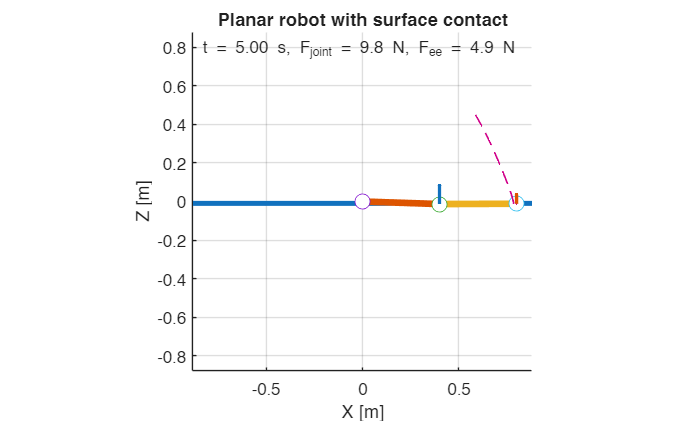



if show_animation
    %% Animation
    %
    % The animation function must also support the updated contact model.
    % Pass dq so that the displayed contact forces include damping.
    
    animate_planar_robot_with_floor( ...
        t, ...
        q, ...
        dq, ...
        param);
end



if show_graphs
    %% Joint angles
    
    figure;
    
    plot( ...
        t, ...
        rad2deg(q(:, 1)), ...
        'LineWidth', 1.5);
    
    hold on;
    
    plot( ...
        t, ...
        rad2deg(q(:, 2)), ...
        'LineWidth', 1.5);
    
    grid on;
    
    xlabel('Time [s]');
    ylabel('Joint angle [deg]');
    
    legend( ...
        'q_1', ...
        'q_2', ...
        'Location', 'best');
    
    title('Joint angles with surface contact');
    
    %% Joint velocities
    
    figure;
    
    plot( ...
        t, ...
        dq(:, 1), ...
        'LineWidth', 1.5);
    
    hold on;
    
    plot( ...
        t, ...
        dq(:, 2), ...
        'LineWidth', 1.5);
    
    grid on;
    
    xlabel('Time [s]');
    ylabel('Joint velocity [rad/s]');
    
    legend( ...
        'dq_1', ...
        'dq_2', ...
        'Location', 'best');
    
    title('Joint velocities with surface contact');
    
    %% Joint accelerations
    
    figure;
    
    plot( ...
        t, ...
        ddq(:, 1), ...
        'LineWidth', 1.5);
    
    hold on;
    
    plot( ...
        t, ...
        ddq(:, 2), ...
        'LineWidth', 1.5);
    
    grid on;
    
    xlabel('Time [s]');
    ylabel('Joint acceleration [rad/s^2]');
    
    legend( ...
        'ddq_1', ...
        'ddq_2', ...
        'Location', 'best');
    
    title('Joint accelerations with surface contact');
    
    %% Contact-point heights
    
    figure;
    
    plot( ...
        t, ...
        joint_position(:, 2), ...
        'LineWidth', 1.5);
    
    hold on;
    
    plot( ...
        t, ...
        ee_position(:, 2), ...
        'LineWidth', 1.5);
    
    yline( ...
        param.z_floor, ...
        '--', ...
        'Floor');
    
    grid on;
    
    xlabel('Time [s]');
    ylabel('Z position [m]');
    
    legend( ...
        'Second joint', ...
        'End effector', ...
        'Floor', ...
        'Location', 'best');
    
    title('Contact-point heights');
    
    %% Penetration
    
    figure;
    
    plot( ...
        t, ...
        1000 * joint_penetration, ...
        'LineWidth', 1.5);
    
    hold on;
    
    plot( ...
        t, ...
        1000 * ee_penetration, ...
        'LineWidth', 1.5);
    
    grid on;
    
    xlabel('Time [s]');
    ylabel('Penetration [mm]');
    
    legend( ...
        'Second joint', ...
        'End effector', ...
        'Location', 'best');
    
    title('Surface penetration');
    
    %% Normal contact forces
    
    figure;
    
    plot( ...
        t, ...
        joint_contact_force(:, 2), ...
        'LineWidth', 1.5);
    
    hold on;
    
    plot( ...
        t, ...
        ee_contact_force(:, 2), ...
        'LineWidth', 1.5);
    
    plot( ...
        t, ...
        total_contact_force(:, 2), ...
        '--', ...
        'LineWidth', 1.5);
    
    grid on;
    
    xlabel('Time [s]');
    ylabel('Normal contact force [N]');
    
    legend( ...
        'Second joint', ...
        'End effector', ...
        'Total', ...
        'Location', 'best');
    
    title('Normal surface-contact forces');
    
    %% Contact torque from second-joint contact
    
    figure;
    
    plot( ...
        t, ...
        joint_contact_torque(:, 1), ...
        'LineWidth', 1.5);
    
    hold on;
    
    plot( ...
        t, ...
        joint_contact_torque(:, 2), ...
        'LineWidth', 1.5);
    
    grid on;
    
    xlabel('Time [s]');
    ylabel('Joint torque [Nm]');
    
    legend( ...
        '\tau_{joint,1}', ...
        '\tau_{joint,2}', ...
        'Location', 'best');
    
    title('Torque generated by second-joint contact');
    
    %% Contact torque from end-effector contact
    
    figure;
    
    plot( ...
        t, ...
        ee_contact_torque(:, 1), ...
        'LineWidth', 1.5);
    
    hold on;
    
    plot( ...
        t, ...
        ee_contact_torque(:, 2), ...
        'LineWidth', 1.5);
    
    grid on;
    
    xlabel('Time [s]');
    ylabel('Joint torque [Nm]');
    
    legend( ...
        '\tau_{ee,1}', ...
        '\tau_{ee,2}', ...
        'Location', 'best');
    
    title('Torque generated by end-effector contact');
    
    %% Total contact torque
    
    figure;
    
    plot( ...
        t, ...
        total_contact_torque(:, 1), ...
        'LineWidth', 1.5);
    
    hold on;
    
    plot( ...
        t, ...
        total_contact_torque(:, 2), ...
        'LineWidth', 1.5);
    
    grid on;
    
    xlabel('Time [s]');
    ylabel('Joint torque [Nm]');
    
    legend( ...
        '\tau_{contact,1}', ...
        '\tau_{contact,2}', ...
        'Location', 'best');
    
    title('Total joint torque generated by contact');
    
    %% Joint friction torque
    
    figure;
    
    plot( ...
        t, ...
        friction_torque_log(:, 1), ...
        'LineWidth', 1.5);
    
    hold on;
    
    plot( ...
        t, ...
        friction_torque_log(:, 2), ...
        'LineWidth', 1.5);
    
    grid on;
    
    xlabel('Time [s]');
    ylabel('Friction torque [Nm]');
    
    legend( ...
        '\tau_{fric,1}', ...
        '\tau_{fric,2}', ...
        'Location', 'best');
    
    title('Joint friction torque');
    
    %% Gravity torque
    
    figure;
    
    plot( ...
        t, ...
        G_log(:, 1), ...
        'LineWidth', 1.5);
    
    hold on;
    
    plot( ...
        t, ...
        G_log(:, 2), ...
        'LineWidth', 1.5);
    
    grid on;
    
    xlabel('Time [s]');
    ylabel('Gravity torque [Nm]');
    
    legend( ...
        'G_1', ...
        'G_2', ...
        'Location', 'best');
    
    title('Gravity torque');
    
    %% Mechanical energy
    
    figure;
    
    plot( ...
        t, ...
        kinetic_energy, ...
        'LineWidth', 1.5);
    
    hold on;
    
    plot( ...
        t, ...
        potential_energy, ...
        'LineWidth', 1.5);
    
    plot( ...
        t, ...
        mechanical_energy, ...
        'LineWidth', 1.5);
    
    grid on;
    
    xlabel('Time [s]');
    ylabel('Energy [J]');
    
    legend( ...
        'Kinetic energy', ...
        'Potential energy', ...
        'Mechanical energy', ...
        'Location', 'best');
    
    title('Mechanical energy with contact and friction');
    
    %% Friction dissipation power
    
    figure;
    
    plot( ...
        t, ...
        friction_power, ...
        'LineWidth', 1.5);
    
    grid on;
    
    xlabel('Time [s]');
    ylabel('Dissipation power [W]');
    
    title('Mechanical power dissipated by joint friction');
    
    %% Contact states
    
    figure;
    
    stairs( ...
        t, ...
        double(joint_contact_state), ...
        'LineWidth', 1.5);
    
    hold on;
    
    stairs( ...
        t, ...
        double(ee_contact_state), ...
        'LineWidth', 1.5);
    
    grid on;
    
    ylim([-0.1, 1.1]);
    
    xlabel('Time [s]');
    ylabel('Contact state');
    
    yticks([0, 1]);
    
    yticklabels({ ...
        'No contact', ...
        'Contact'});
    
    legend( ...
        'Second joint', ...
        'End effector', ...
        'Location', 'best');
    
    title('Surface-contact states');
end